importar tabla de datos

tabla = readtable('SMwr_Ex_01.txt');
A=tabla.A;
B=tabla.B;
Dat=tabla.Dato;

Dispersion de la serie de datos

Serie (A, # dato)

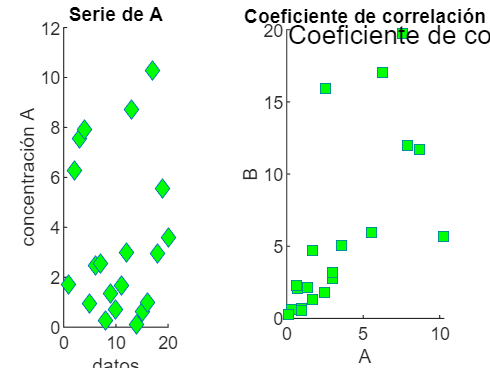

subplot (1,3,1), scatter(Dat,A,'d','MarkerFaceColor', 'green'), title('Serie de A'), xlabel('datos'), ylabel('concentración A');

Serie (B, # dato)

subplot (1,3,2), scatter(Dat,B,'*','MarkerFaceColor', 'red'),title('Serie de B'), xlabel('datos'), ylabel('Concentración B'); 

Serie (A , B)

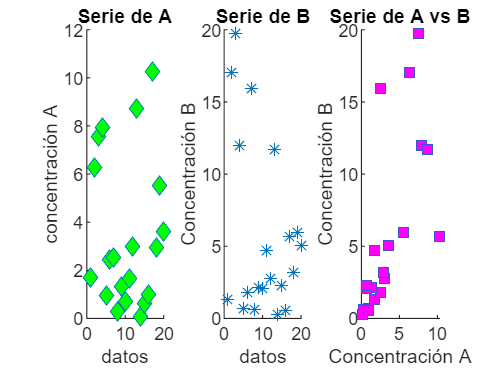

subplot (1,3,3), scatter(A,B,'s','MarkerFaceColor', 'm'),title('Serie de A vs B'), xlabel('Concentración A'), ylabel('Concentración B');

1.

subplot(3,1,1),histogram(A,'BinWidth',1), title('Histograma clase 1')%Histograma A con anchura de clase 1
xlabel('Valores');
ylabel('Frecuencia');
subplot(3,1,2),histogram(A,'BinWidth',2), title('Histograma clase 2')%Histograma A con anchura de clase 2
xlabel('Valores');
ylabel('Frecuencia');
subplot(3,1,3),histogram(A,'BinWidth',5), title('Histograma clase 5')%Histograma A con anchura de clase 2
xlabel('Valores');
ylabel('Frecuencia');

Proporcion de los datos de A=0.25

PA=sum(A>=5 & A<=10);
fA=PA/length(A);

2.

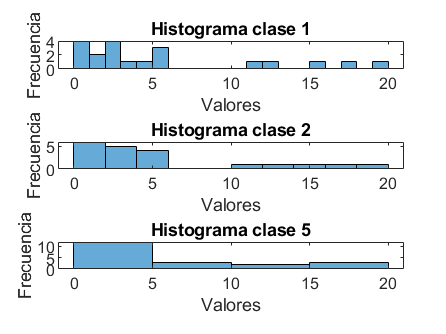

subplot(3,1,1),histogram(B,'BinWidth',1), title('Histograma clase 1')%Histograma A con anchura de clase 1
xlabel('Valores');
ylabel('Frecuencia');
subplot(3,1,2),histogram(B,'BinWidth',2), title('Histograma clase 2')%Histograma A con anchura de clase 2
xlabel('Valores');
ylabel('Frecuencia');
subplot(3,1,3),histogram(B,'BinWidth',5), title('Histograma clase 5')%Histograma A con anchura de clase 2
xlabel('Valores');
ylabel('Frecuencia');

Proporcion de los datos de B=0.1

n=sum(B>=10 & B<=15);
PB=n/length(A);
disp(PB);

    0.1000



3.

Distribución acumulativa de A y B

Ac1=cumsum(A)/sum(A);
subplot (1,2,1), plot(Ac1),title('Acumulada de A'), xlabel('Acumulada'), ylabel('frecuencia')
Ac2=cumsum(B)/sum(B);
subplot (1,2,2), plot(Ac2),title('Acumulada de B'), xlabel('Acumulada'), ylabel('frecuencia')

4.

Estadistica descriptiva A

media_A=mean(A);
varianza_A=var(A);
asimetria_A=skewness(A);
curtosis_A=kurtosis(A);
cuantiles_A=quantile(A,[.25 .50 .75]);
mediana_A=median(A);
iqr_A=iqr(A);

Estadistica descriptiva B

media_B=mean(B);
varianza_B=var(B);
asimetria_B=skewness(B);
curtosis_B=kurtosis(B);
cuantiles_B=quantile(B,[.25 .50 .75]);
mediana_B=median(B);
iqr_B=iqr(B);


5.

A_B=[A;B];
grupos = [ones(length(A), 1); 2*ones(length(B), 1)];
boxplot(A_B, grupos, 'Labels', {'A', 'B'});
xlabel('Grupos');
ylabel('A-B');
title('Diagrama de caja y bigotes para A & B');

En B hay un valor atipico con una concentración 19.74 mg/kg

6.

Concentración crítica en A

CA = 5; 

área = m^2 

a = 8000;  

Área aproximada a ser limpiada=2400m^2

AA=(sum(A>5))/length(A)*a;

7.

Concentración crítica en B

CB = 10; 

Área aproximada a ser limpiada=2000m^2

AB=(sum(B>10))/length(B)*a;


8.

Coeficiente de correlación entre A y B

corr=corrcoef(A,B);
disp(corr);

    1.0000    0.6738
    0.6738    1.0000



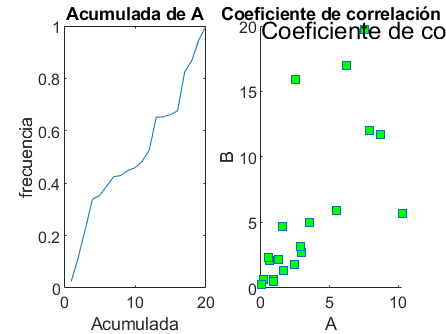

coefficients = polyfit(A, B, 1);
slope = coefficients(1);
intercept = coefficients(2);
scatter(A,B,'s','MarkerFaceColor', 'g');
hold on;
text(min(A), max(B), sprintf('Coeficiente de correlación: %.2f', corr(1,2)), 'FontSize', 12, 'HorizontalAlignment', 'left');
title('Coeficiente de correlación');
xlabel('A');
ylabel('B');
hold on;

9.

PA=sum(A<5)/20;
PB=sum(B<10)/20;
disp(PB);

    0.7500



10.

PAA=sum(A<5)/20;
PBB=sum(B<10)/20;
disp(PBB);

    0.7500

